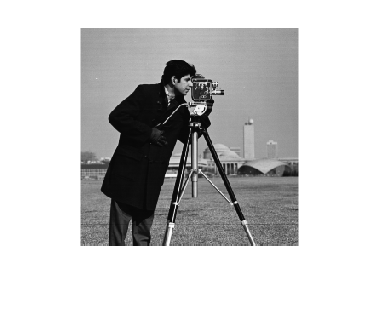

clear
cm=imread('cameraman.tif');

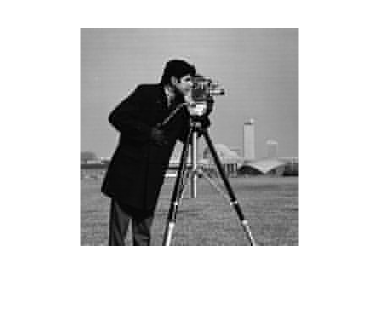

cm=im2double(cm);
T=dctmtx(8);  %T为8*8 DCT变换矩阵
%定义正dct变换的匿名函数，block_struct是MATLAB内置结构变量
dct = @(block_struct) T*block_struct.data*T'; 
B=blockproc(cm,[8,8],dct);    %正dct变换
mask=[1,1,1,1,zeros(1,4);
    1,1,1,zeros(1,5);
    1,1,zeros(1,6);
    1,zeros(1,7);zeros(4,8)];  %压缩掩膜矩阵
B2=blockproc(B,[8,8],@(block_struct)mask.*block_struct.data);%提取10个低频系数
invdct=@(block_struct) T'*block_struct.data*T; %逆dct变换函数
cm2=blockproc(B2,[8,8],invdct);  %逆dct变换
imshow(cm)
imshow(cm2)